# Problem Set 1: Spike Sorting

CPNS 35600, Mia Paletta, Spring 2021

## P1: Backyard Brains data

Load BYB data, sampled at 32,000Hz, and plot one second of the raw data and high pass filtered data.

% load the data

BYB = load("BYB_cockroach_data.mat");

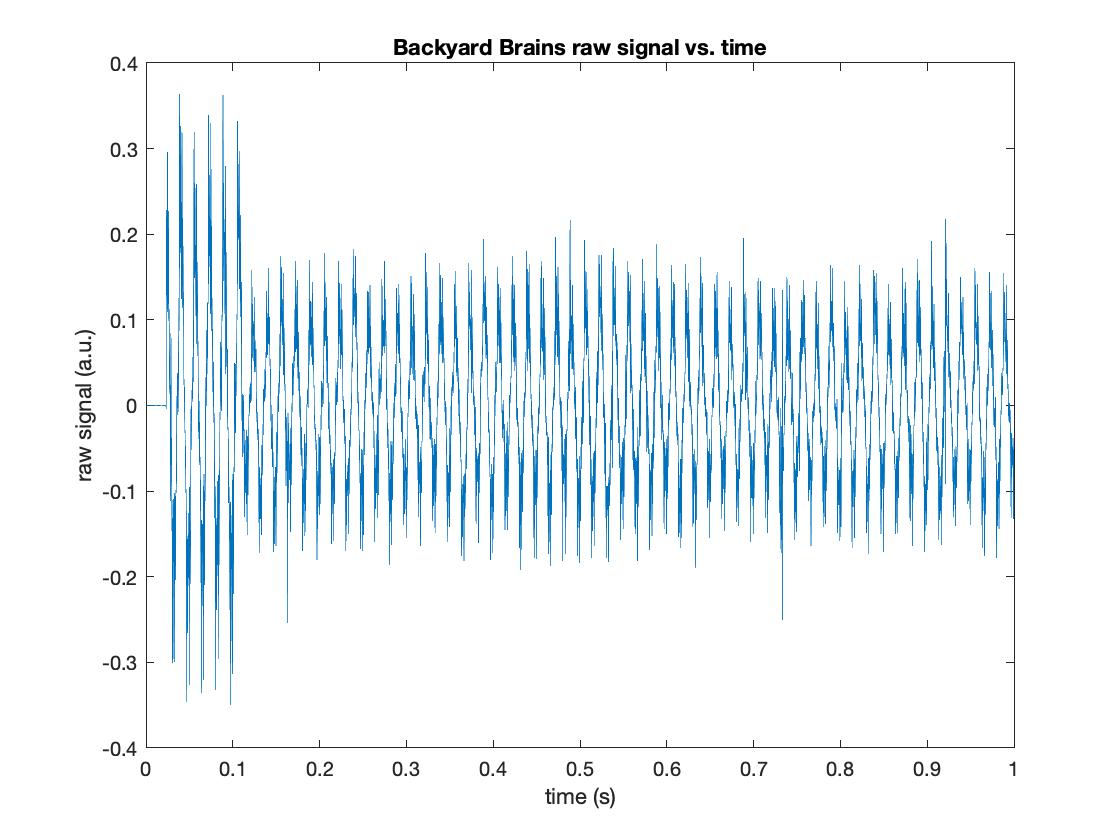

% plot 1s (32,000 samples) of raw and filtered data

figure
plot(BYB.x_time_points(1:32000), BYB.signal_raw(1:32000))
xlabel('time (s)')
ylabel('raw signal (a.u.)')
title('Backyard Brains raw signal vs. time')

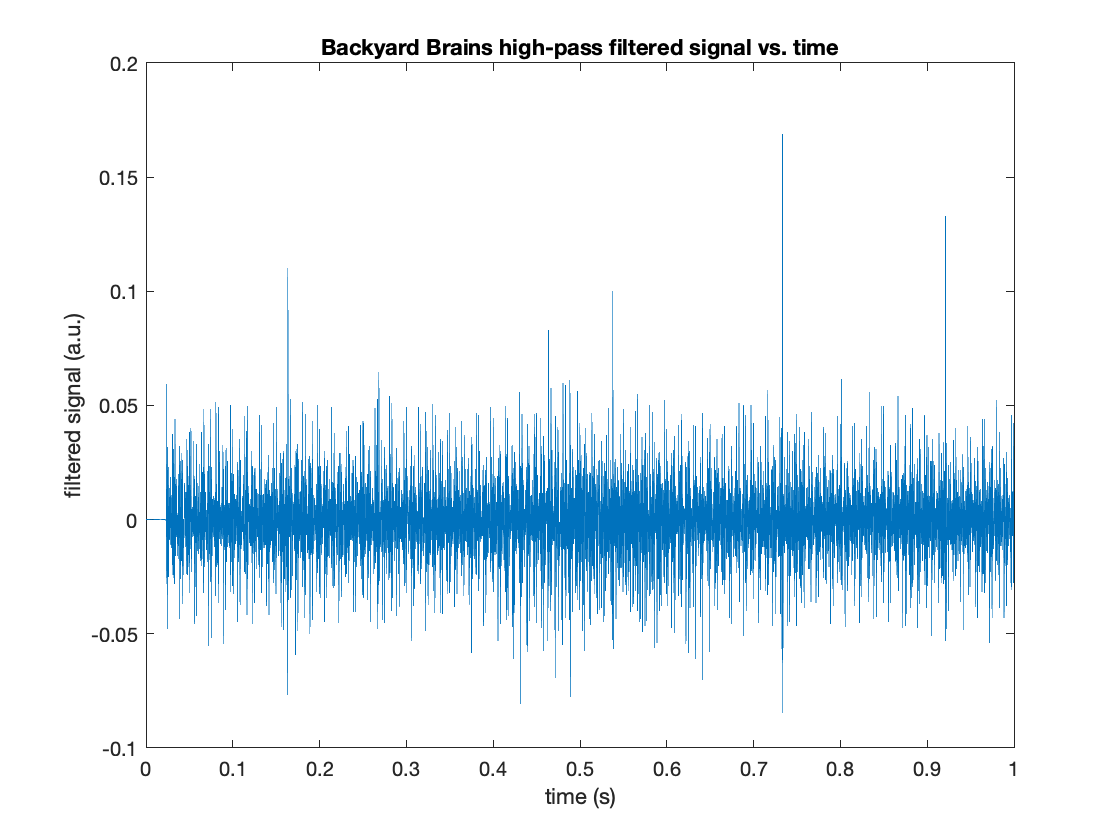



figure
plot(BYB.x_time_points(1:32000), BYB.signal_highpass_500Hz(1:32000))
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
title('Backyard Brains high-pass filtered signal vs. time')

**High pass filtering this data removes component frequencies from the signal that are at frequencies lower than the threshold for the filter, which in this case, is set at 500Hz. So, any components of the signal at frequencies lower than 500Hz have been removed. We can see this reflected in the filtered signal, where slower oscillations from the raw signal are no longer present.**

## P2: Pick a recording and plot the signal

%load the data

L = load("groupL_cockroach_data_19.mat");
R = load("groupR_cockroach_data_19.mat");
R2 = load("groupR2_cockroach_data_19.mat");

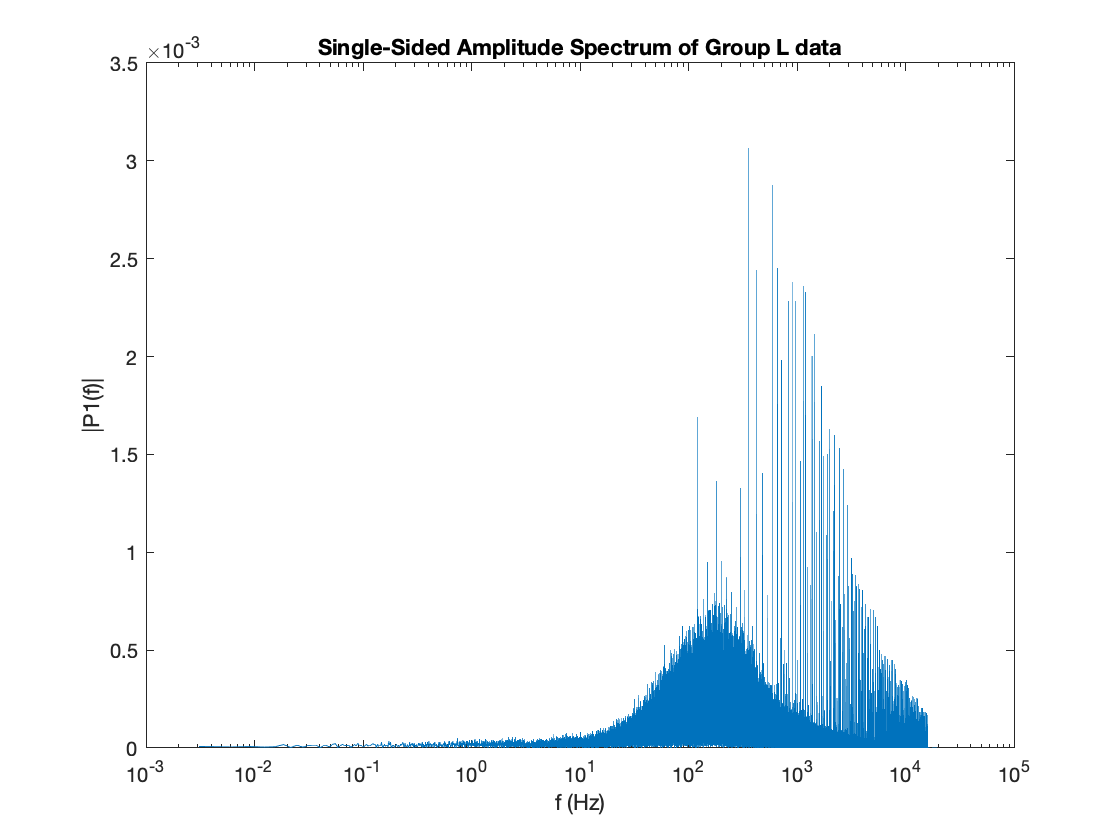

% FFT of group L data

Fs = 44100;
L_signal = length(L.signal_raw);

Y = fft(L.signal_raw);

% Compute the two-sided spectrum P2.
P2 = abs(Y/L_signal);
P1 = P2(1:L_signal/2+1);
P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain f and plot the single-sided amplitude spectrum P1. 
f = Fs*(0:(L_signal/2))/L_signal;
figure
semilogx(f,P1)
% xlim([0 100])
title('Single-Sided Amplitude Spectrum of Group L data')
xlabel('f (Hz)')
ylabel('|P1(f)|')

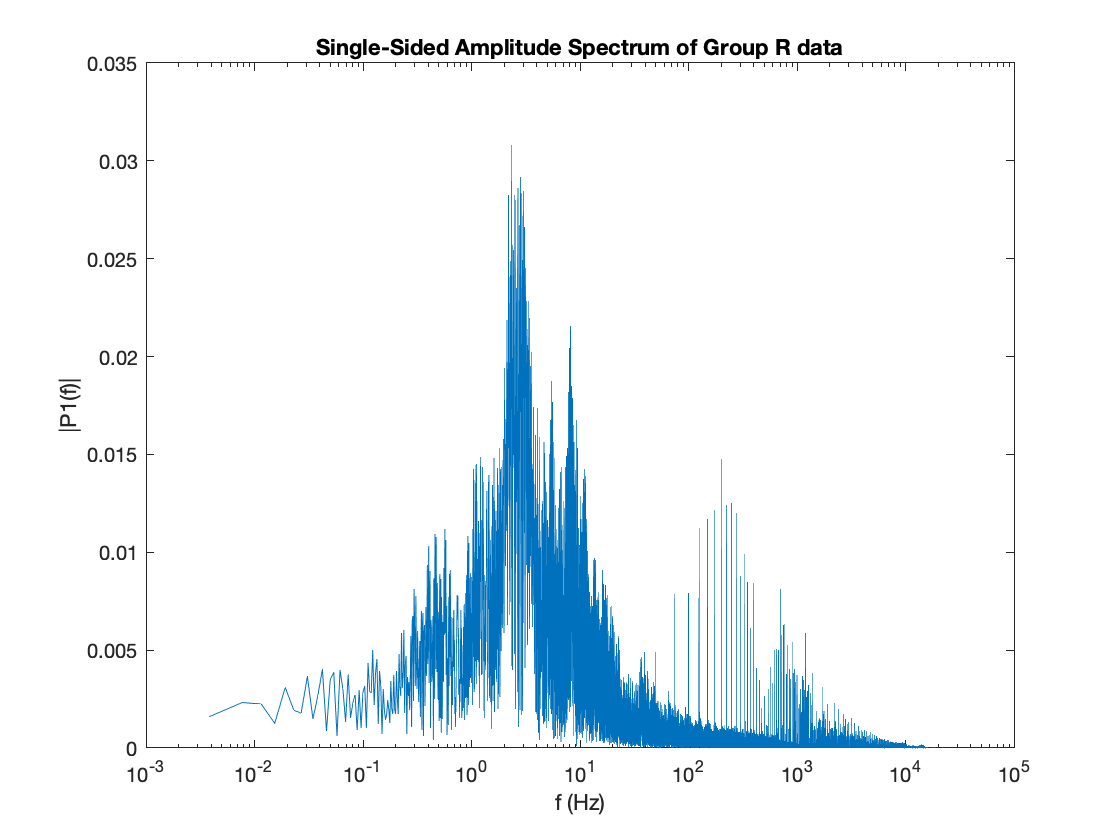

% FFT of group R data

Fs = 44100;
R_signal = length(R.signal_raw);

Y = fft(R.signal_raw);

% Compute the two-sided spectrum P2.
P2 = abs(Y/R_signal);
P1 = P2(1:R_signal/2+1);
P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain f and plot the single-sided amplitude spectrum P1. 
f = Fs*(0:(R_signal/2))/R_signal;
figure
semilogx(f,P1)
% xlim([0 100])
title('Single-Sided Amplitude Spectrum of Group R data')
xlabel('f (Hz)')
ylabel('|P1(f)|')

% filter the data - highpass w/ threshold at 500Hz

L.signal_filtered = highpass(L.signal_raw, 500, 44100);
R.signal_filtered = highpass(R.signal_raw, 500, 44100);

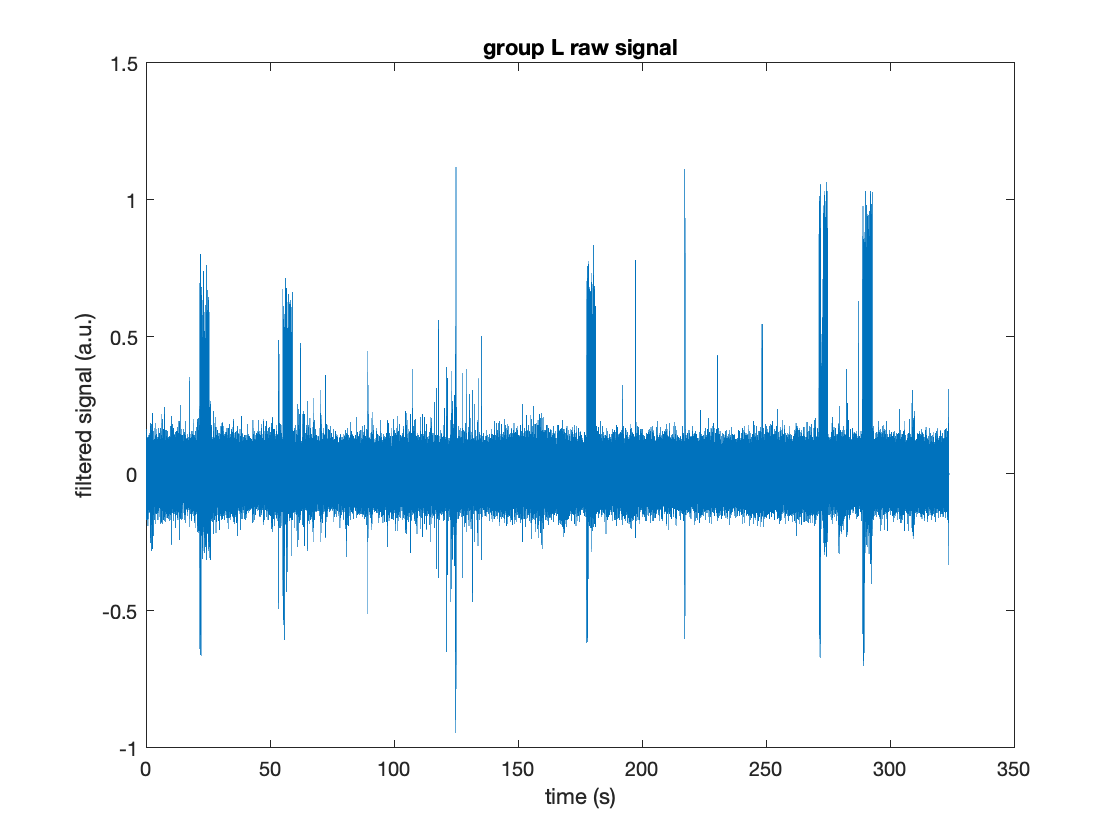

% plot the three recordings and assess which to use

figure
plot(L.x_time_points, L.signal_filtered)
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
title('group L raw signal')

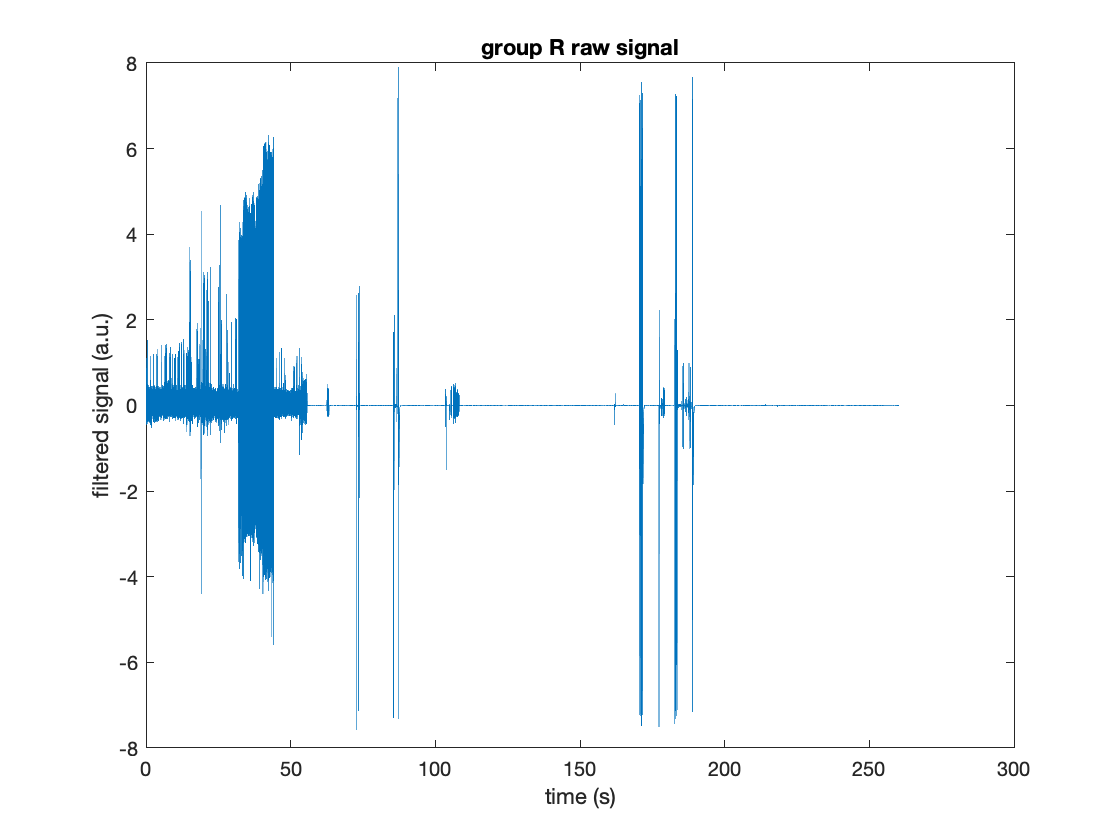


figure
plot(R.x_time_points, R.signal_raw)
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
title('group R raw signal')

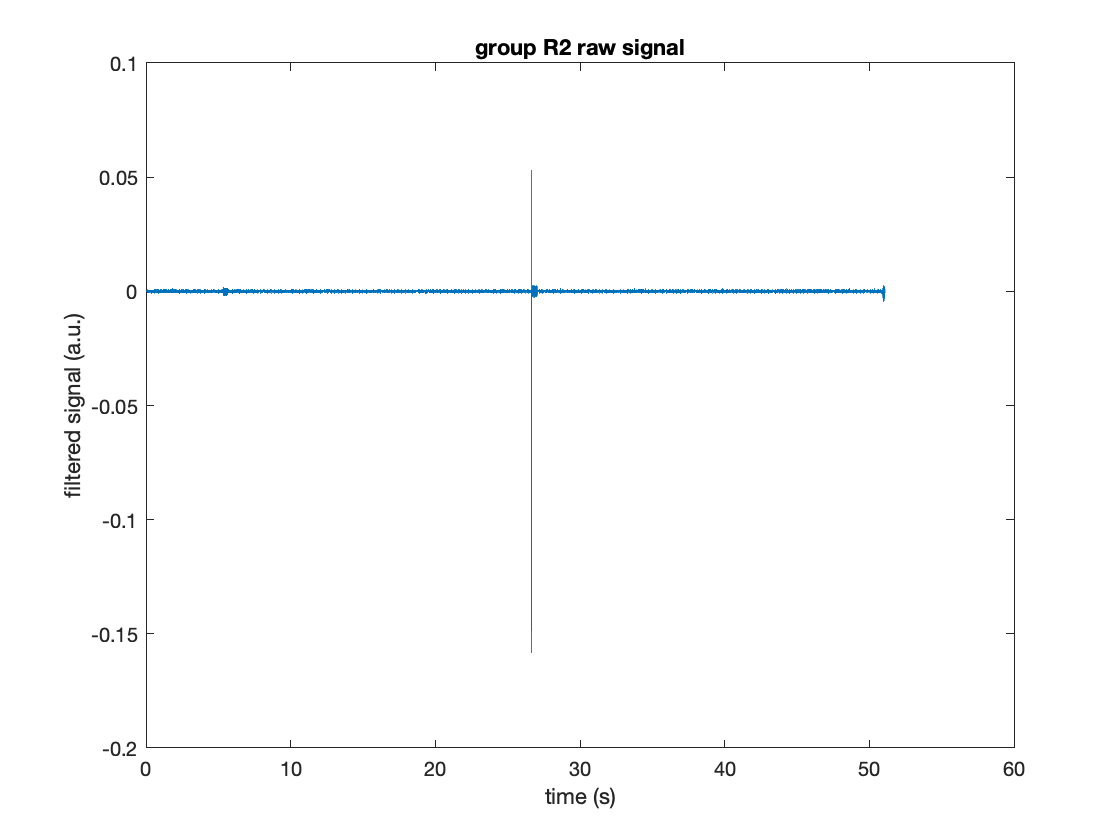


figure
plot(R2.x_time_points, R2.signal_raw)
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
title('group R2 raw signal')

**Originally, I chose to analyze the recording from group L because it was the only recording that seemed to show activity for the entire duration of the recording. However, after stepping through some of the later analyses, I decided to switch to group R's recording. The spikes in group L's recordings appeared "clipped" at the peaks when you zoom in on them. This is likely due to some sort of issue in the electronics / recording setup, like having the sensor gain turned up too high, and the amplitude reached the maximum value that the sensor was able to record. Because this could limit the diversity in spike amplitudes and distort the different spike morphologies, I decided to use group R's recording.**

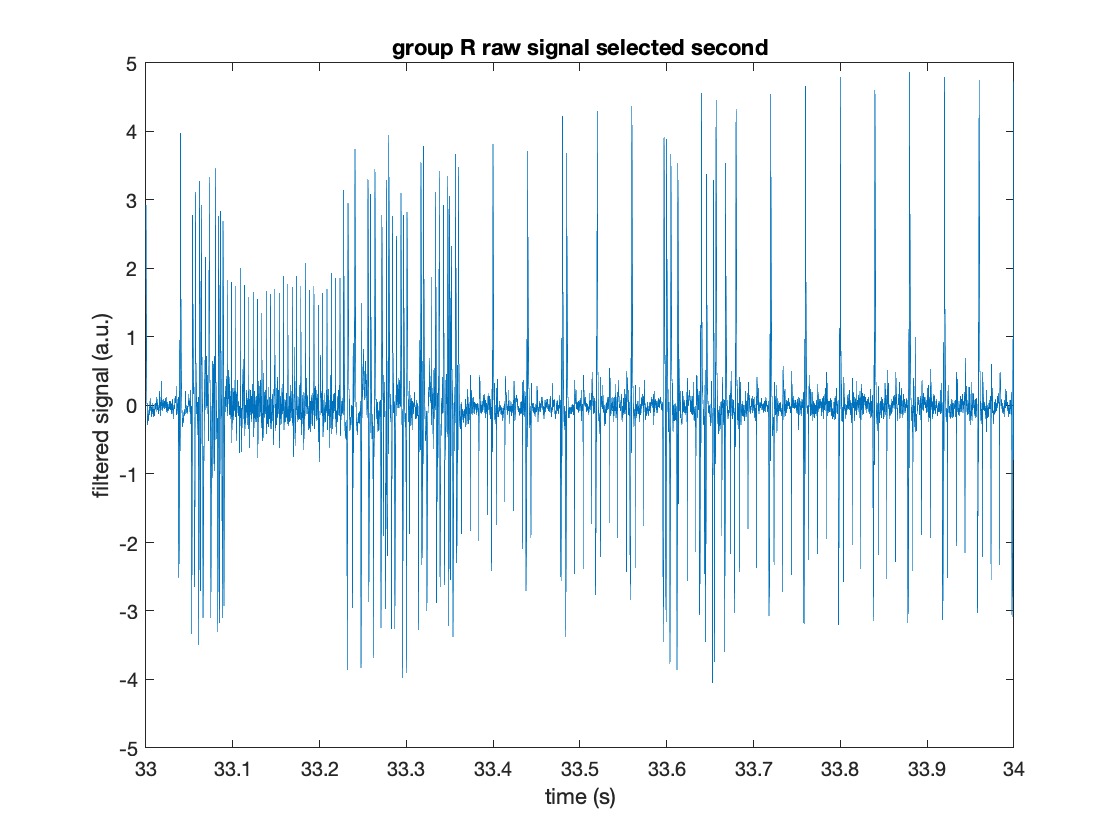

% find a "good" segment of the recording to plot

figure
plot(R.x_time_points(33*44100:34*44100), R.signal_raw(33*44100:34*44100))
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
ylim([-5 5])
title('group R raw signal selected second')

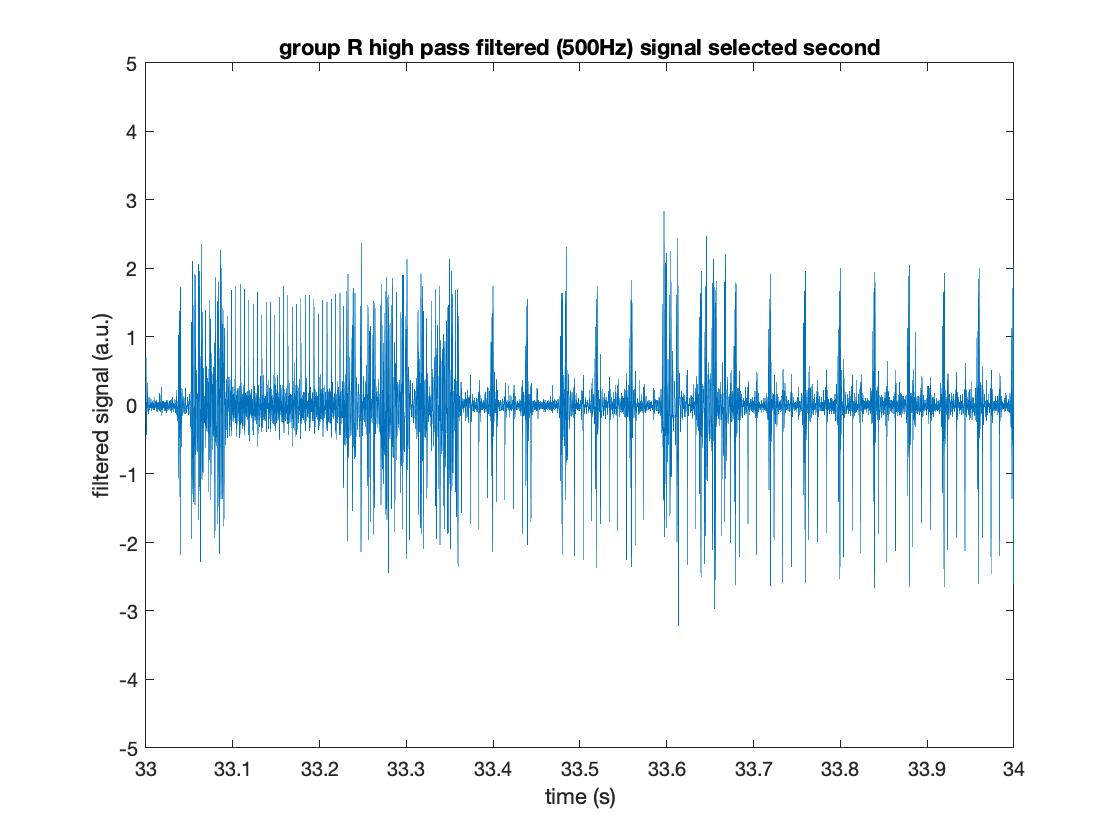


figure
plot(R.x_time_points(33*44100:34*44100), R.signal_filtered(33*44100:34*44100))
xlabel('time (s)')
ylabel('filtered signal (a.u.)')
ylim([-5 5])
title('group R high pass filtered (500Hz) signal selected second')


% make another plot to "zoom in" on some spikes
figure
plot(R.x_time_points(33.15*44100:33.16*44100), R.signal_filtered(33.15*44100:33.16*44100))

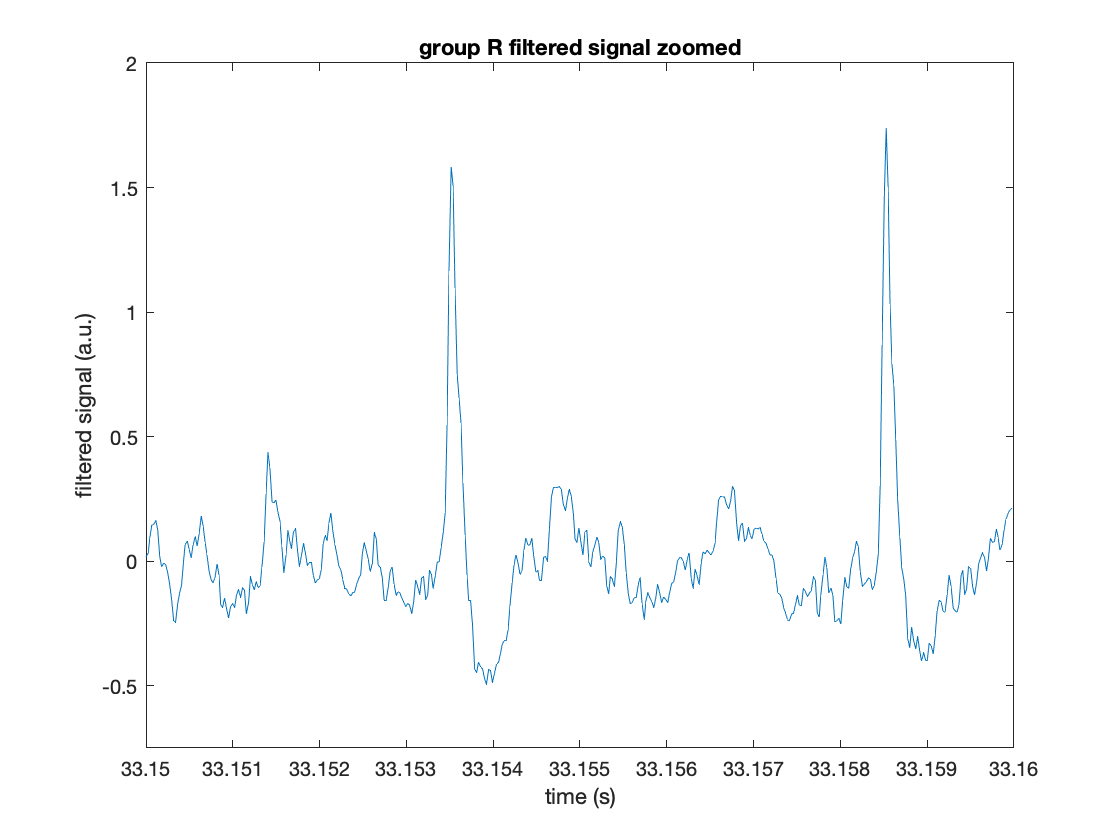

xlabel('time (s)')
ylabel('filtered signal (a.u.)')
ylim([-0.75 2])
title('group R filtered signal zoomed')

## P3: Count spikes in the recording of interest

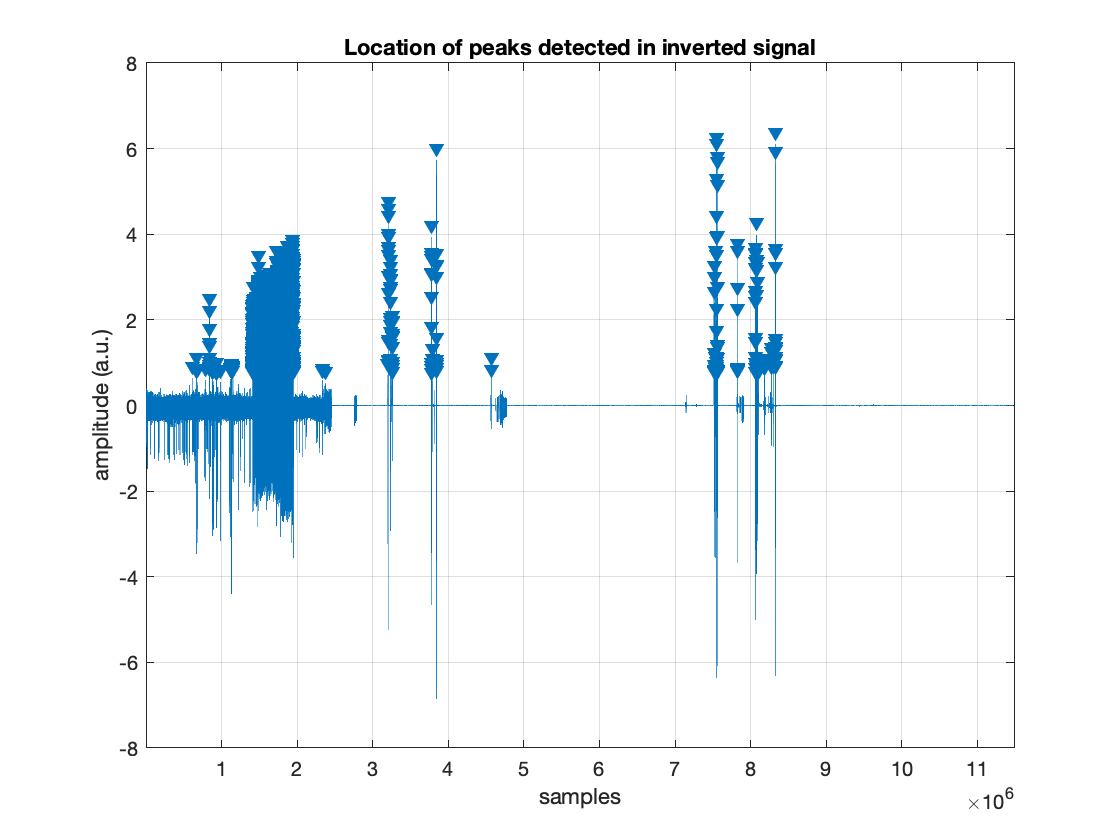

% use findpeaks to find the peaks in the entire recording

R.inverted_signal = R.signal_filtered * -1; %inverted signal to make it so findpeaks was an option

[pks, locs] = findpeaks(R.inverted_signal, "MinPeakHeight", 0.5, 'MinPeakDistance', 66);

figure
findpeaks(R.inverted_signal, "MinPeakHeight", 0.5, 'MinPeakDistance', 0.0015) % make a plot to visualize the peaks
title('Location of peaks detected in inverted signal')
xlabel('samples')
ylabel('amplitude (a.u.)')


fprintf('Using findpeaks, %d spikes were detected in the dataset', length(pks))

Using findpeaks, 1671 spikes were detected in the dataset

**With an amplitude threshold of 0.5, there were 3,555 spikes detected in group R's recording. It is possible this amplitude is too close to the noise floor and may erroneously be detecting noise peaks as spikes, but I am not certain.**

## P4: Visualize spikes in the ~50 samples around peaks

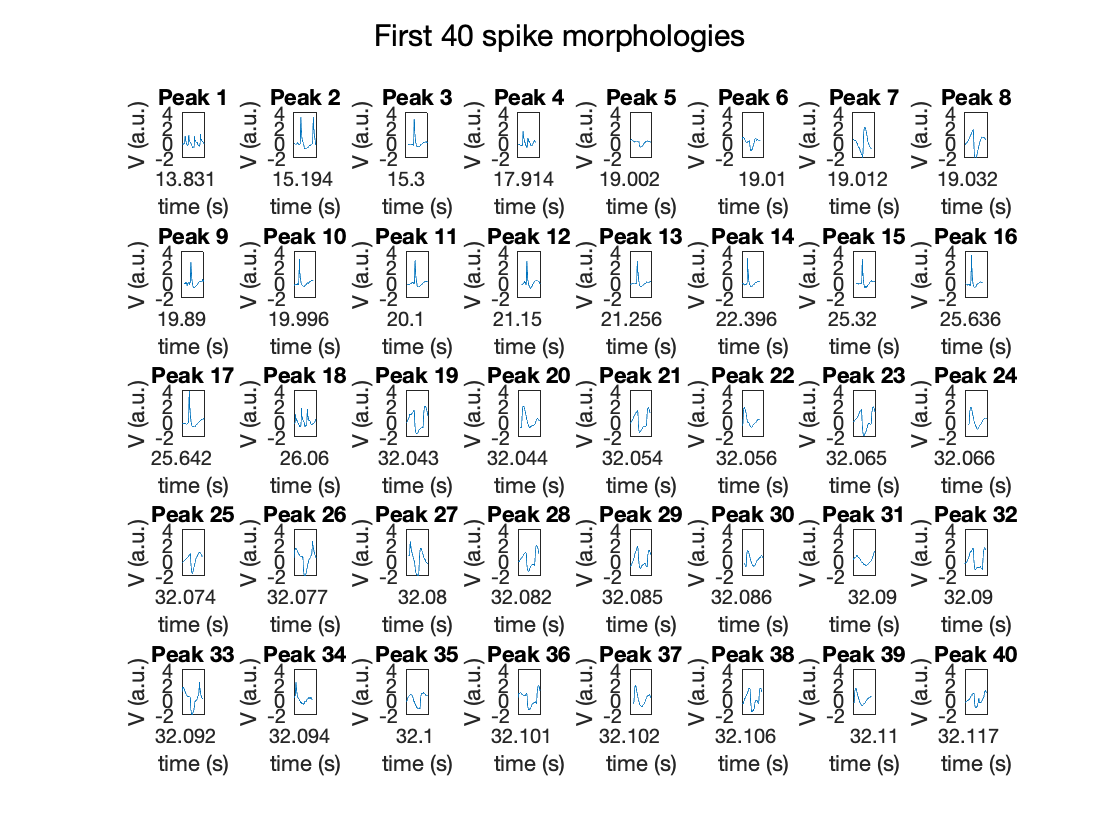

% create a subplot of spikes

for i = 1:40
    subplot(5,8,i)
    plot(R.x_time_points(locs(i)-50:locs(i)+50), R.signal_filtered(locs(i)-50:locs(i)+50))
    xlabel('time (s)')
    ylabel('V (a.u.)')
    ylim([-2 4])
    title(sprintf('Peak %d', i)) 
end

sgtitle('First 40 spike morphologies')

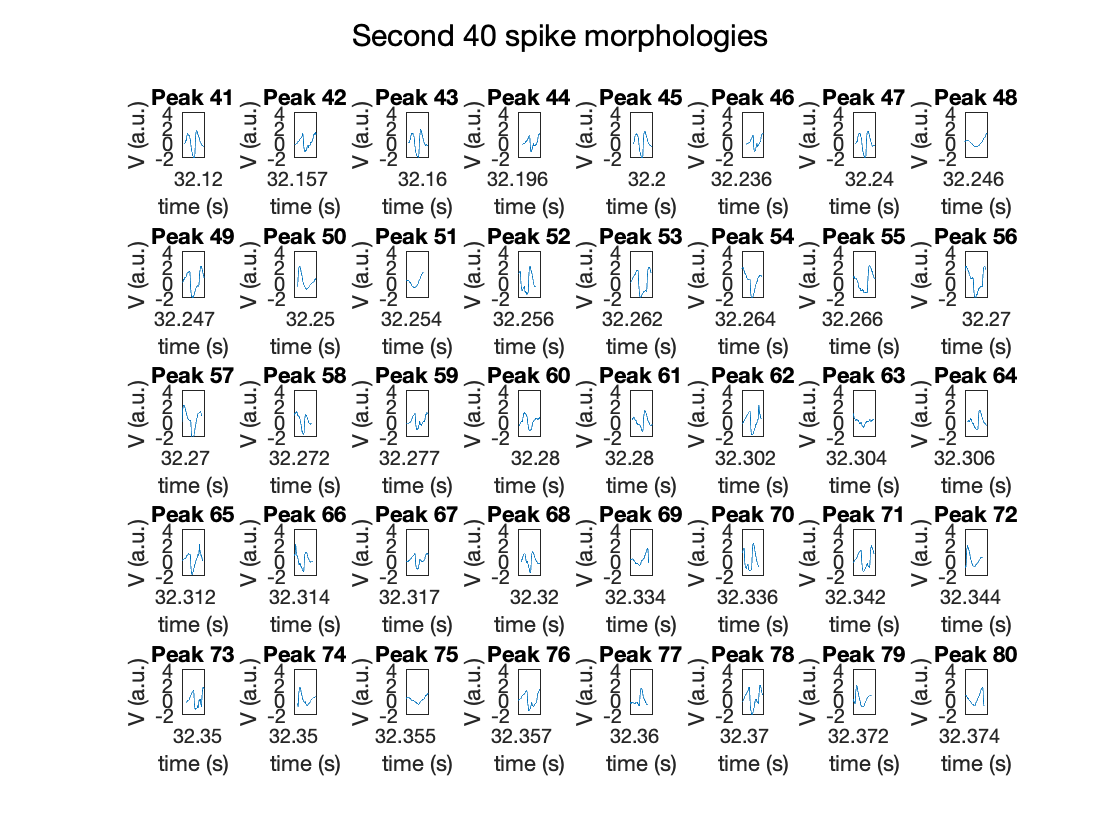


figure
for i = 41:80
    subplot(5,8,i-40)
    plot(R.x_time_points(locs(i)-50:locs(i)+50), R.signal_filtered(locs(i)-50:locs(i)+50))
    xlabel('time (s)')
    ylabel('V (a.u.)')
    ylim([-2 4])
    title(sprintf('Peak %d', i)) 
end

sgtitle('Second 40 spike morphologies')

*Note: Please view these plots at a larger size for a much better viewing experience! They will be separately uploaded in my zip file as PNGs, or you can run the live script and make them larger.*

**In these plots, I see a variety of spike types. One common type in the first 40 spikes was one which shows a large positive transient followed by a slower negative amplitude. It almost appears to be a intracellular action potential, but I don't believe this is actually the case--just similar in shape (example spikes: 3, 9-17). Another is a biphasic type that goes down then up (ex. 7) or up then down (ex. 8, 25). These may be the same type, but from different locations based on the position of the ground electrode. I am unsure about that. There are also a number of spikes that are rapid, smaller, and have a sharp peak followed by a slower depolarization (ex. 1, 4, 18). These seem like they could be noise from me setting my threshold too low, but I am not sure. Another type I see a number of shows a positive peak followed by a long negative peak that is almost square shaped, then another positive peak (ex. 19, 21, 28, 29, 32). I could keep going but I don't want to belabor the point. There are quite a number of spike types, and even in this first set of 80, I am not sure I see any singular type that dominates. Does this mean we are recording from a number of units here?**

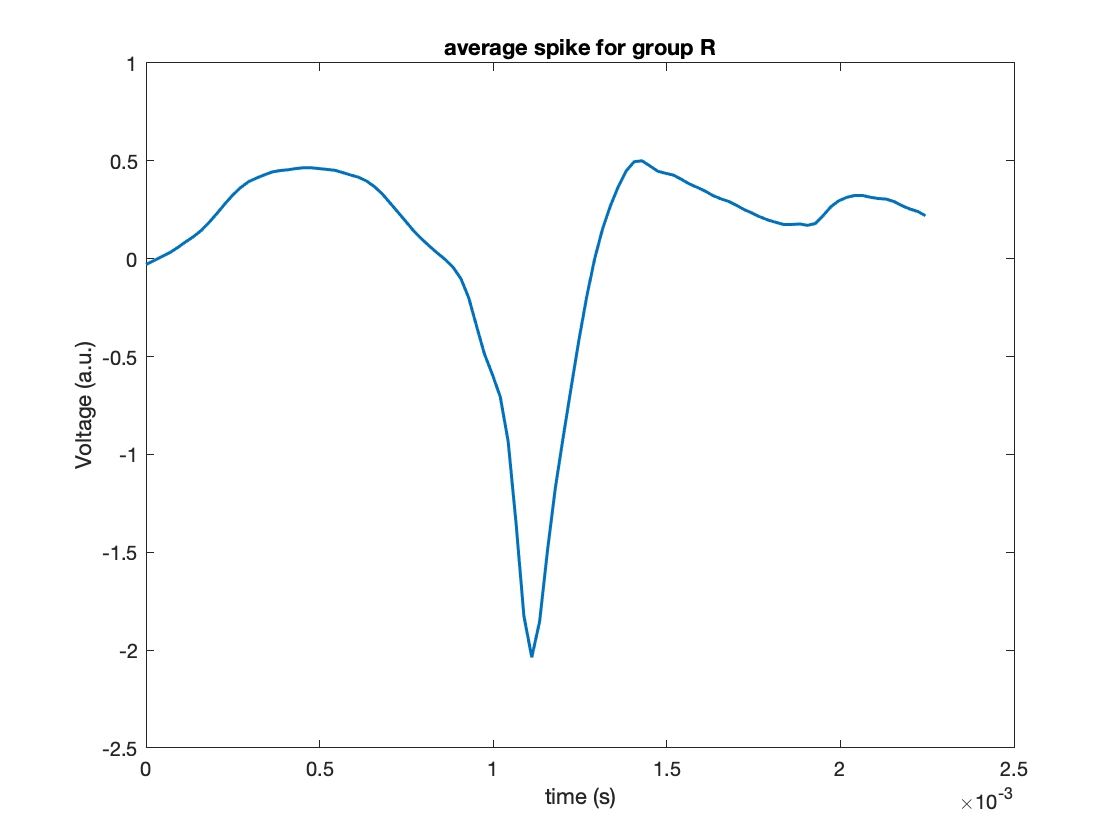

% CORRECTIONS: add average spike shape

avg_spike = mean(clips, 2);
spk_plot_times = (0:99) * 1/44100; % in seconds

figure
plot(spk_plot_times, avg_spike, 'LineWidth', 1.5)
xlabel('time (s)')
ylabel('Voltage (a.u.)')
title('average spike for group R')

## P5: Cluster spikes using simple features from clips

% first, isolate the clips and save them to a variable

clips = [];
clip_times = [];

% take the 100 samples around the peak locations and store values
for i = 1:length(locs)
    clips = [clips R.signal_filtered(locs(i)-49:locs(i)+50)'];
    clip_times = [clip_times R.x_time_points(locs(i)-49:locs(i)+50)'];
end

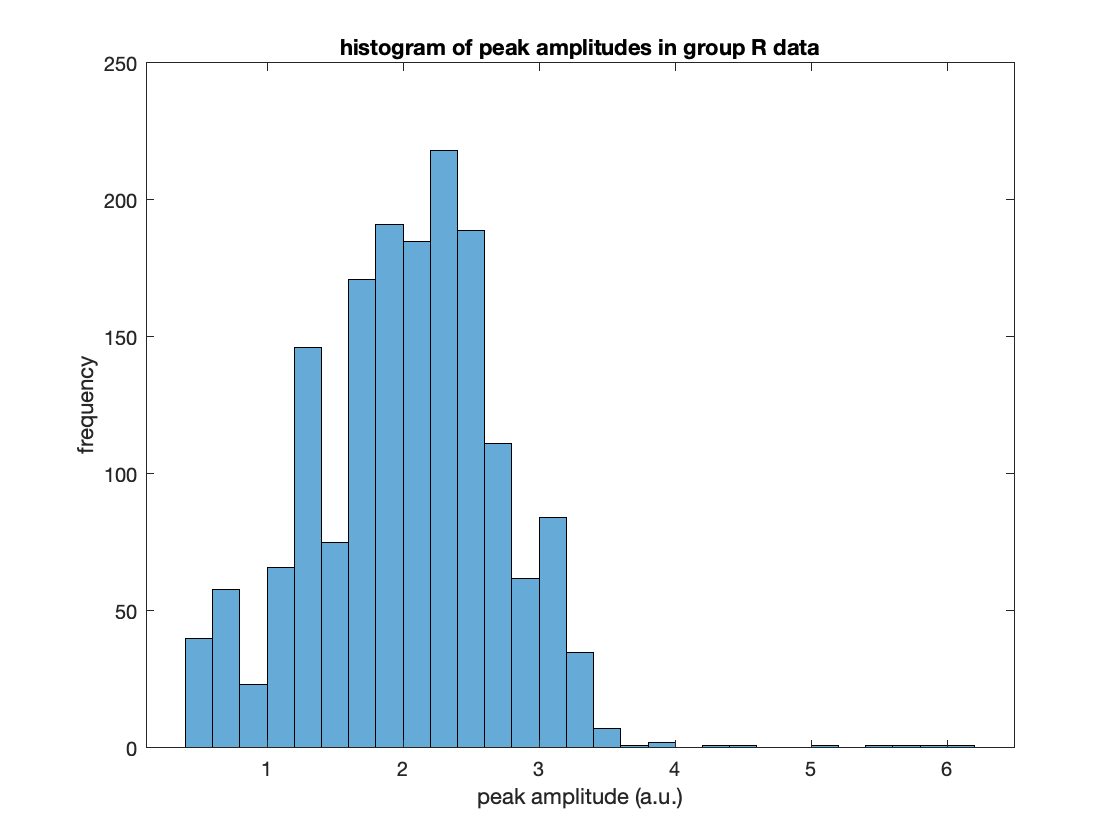

% plot the distribution of the peak amplitudes

figure
histogram(pks)
xlabel('peak amplitude (a.u.)')
ylabel('frequency')
title('histogram of peak amplitudes in group R data')

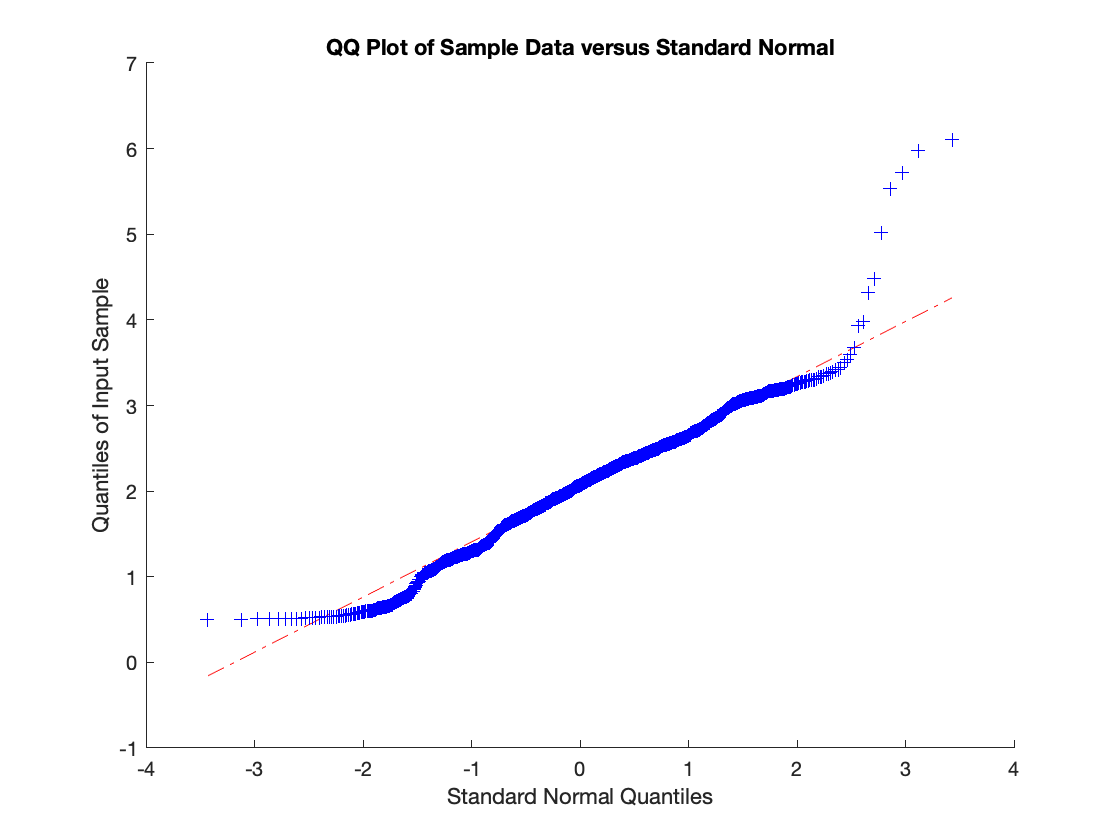


figure
qqplot(pks) %test for normal distribution

**I'm not quite sure I see any clear cut clumps here, but it does seem that there's a large amount of peaks with amplitudes close to 2.5, and another interesting peak around 1.5. Looking at the QQ plot, we can see that the peak amplitudes are approximately normally distributed (based on how well they follow the line), but deviate due to the "tails" of the distribution with a few extreme high or low amplitude peaks.**

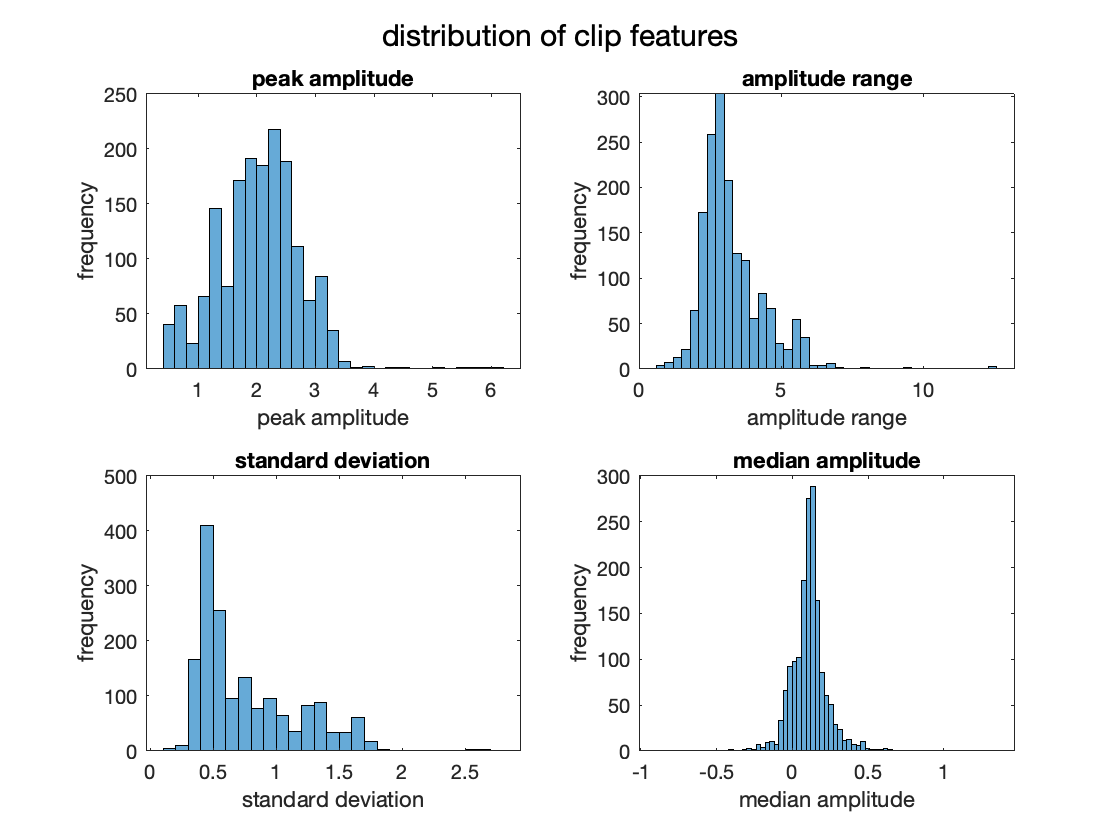

% find some possibly helpful features for the clips

ranges = range(clips);
stdev = std(clips);
median_amp = median(clips);

% make histograms of the features
features = [{pks} {ranges} {stdev} {median_amp}];
feature_names = [{'peak amplitude'} {'amplitude range'} {'standard deviation'} {'median amplitude'}];

figure
for i = 1:4
    subplot(2,2,i)
    histogram(features{i})
    xlabel(feature_names{i})
    ylabel('frequency')
    title(feature_names{i})
end

sgtitle('distribution of clip features')

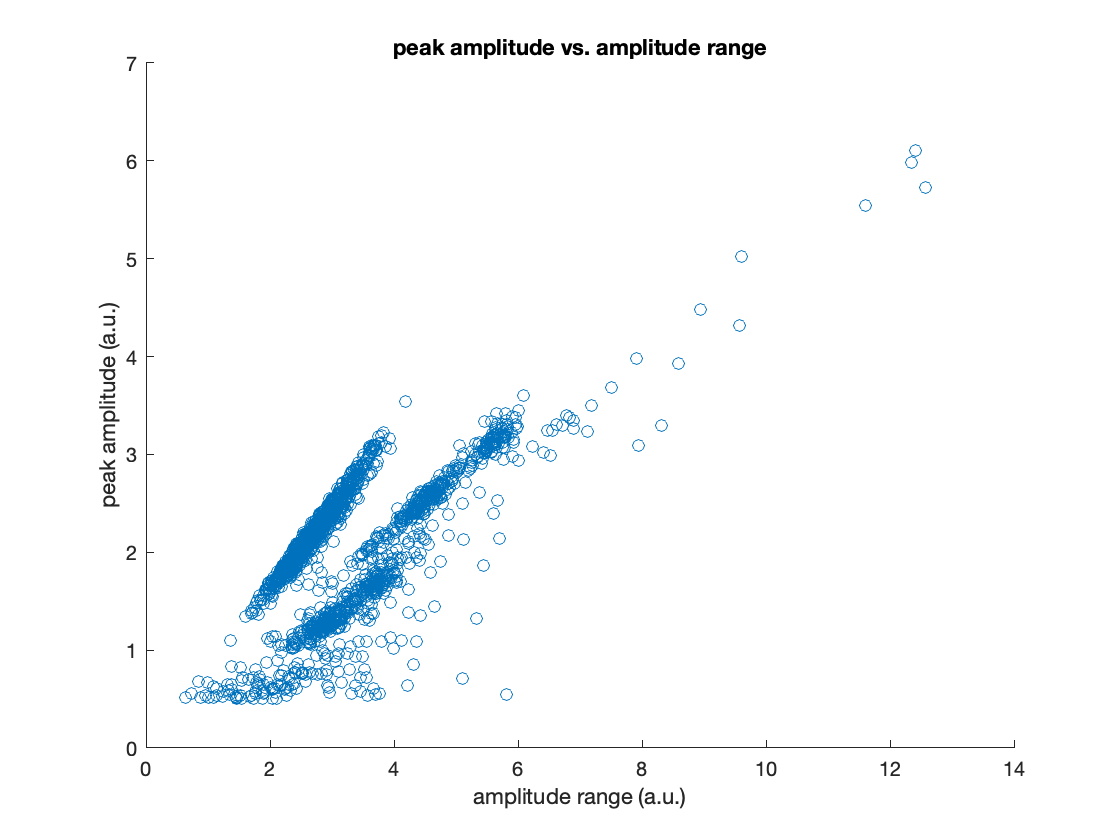


% try plotting the features to check for clusters
% range
figure
scatter(ranges, pks)
xlabel('amplitude range (a.u.)')
% xlim([1 8])
ylabel('peak amplitude (a.u.)')
% ylim([1 4])
title('peak amplitude vs. amplitude range')

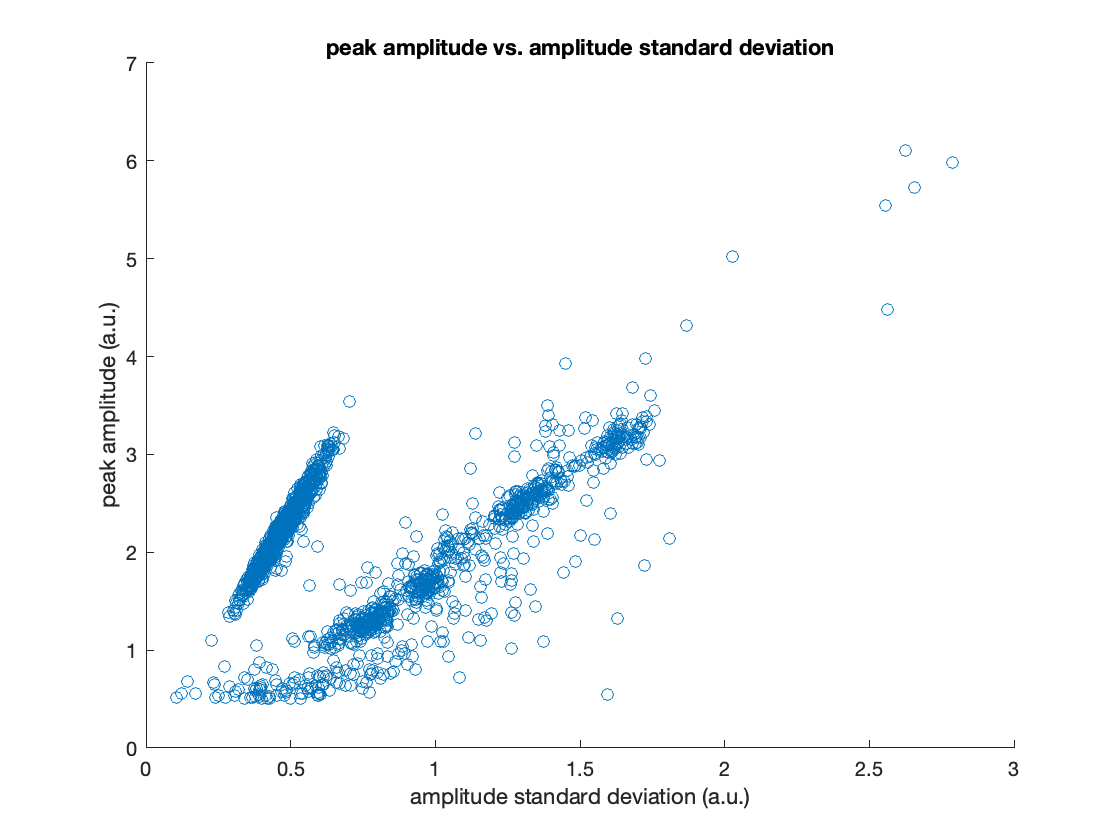


% standard deviation
figure
scatter(stdev, pks)
xlabel('amplitude standard deviation (a.u.)')
% xlim([1 8])
ylabel('peak amplitude (a.u.)')
% ylim([1 4])
title('peak amplitude vs. amplitude standard deviation')

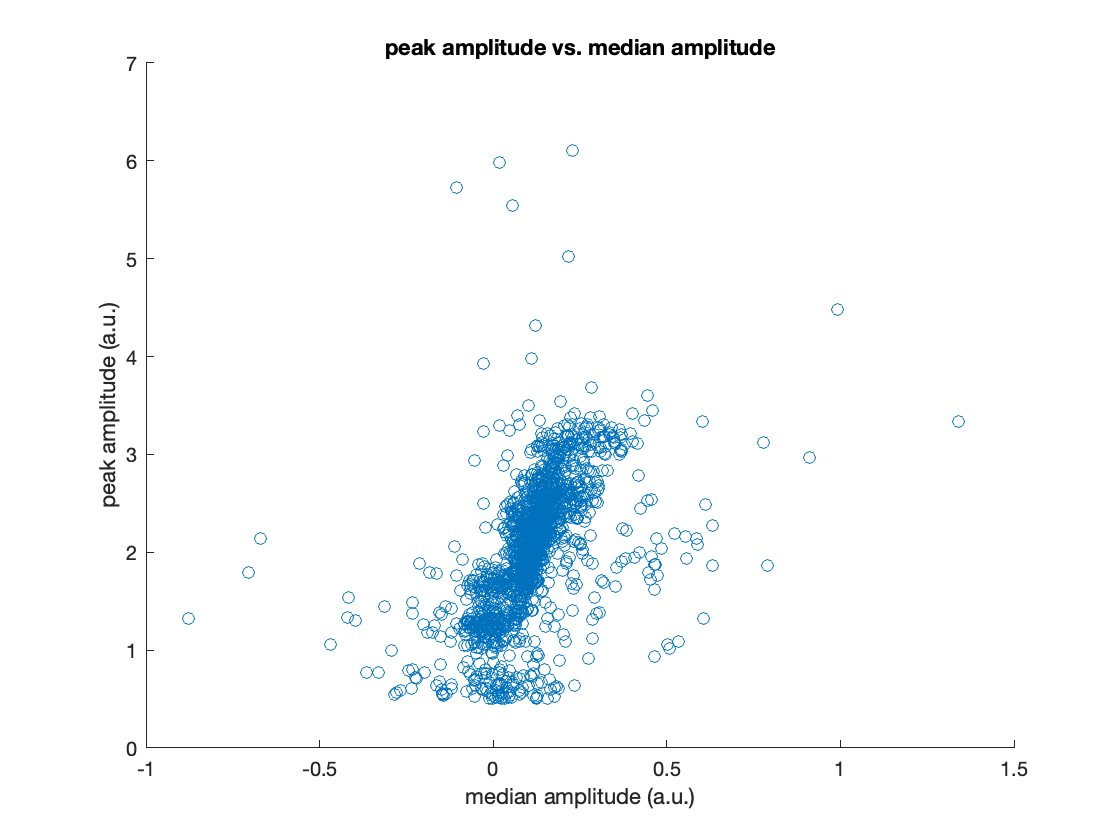


% median amplitude
figure
scatter(median_amp, pks)
xlabel('median amplitude (a.u.)')
% xlim([1 8])
ylabel('peak amplitude (a.u.)')
% ylim([1 4])
title('peak amplitude vs. median amplitude')

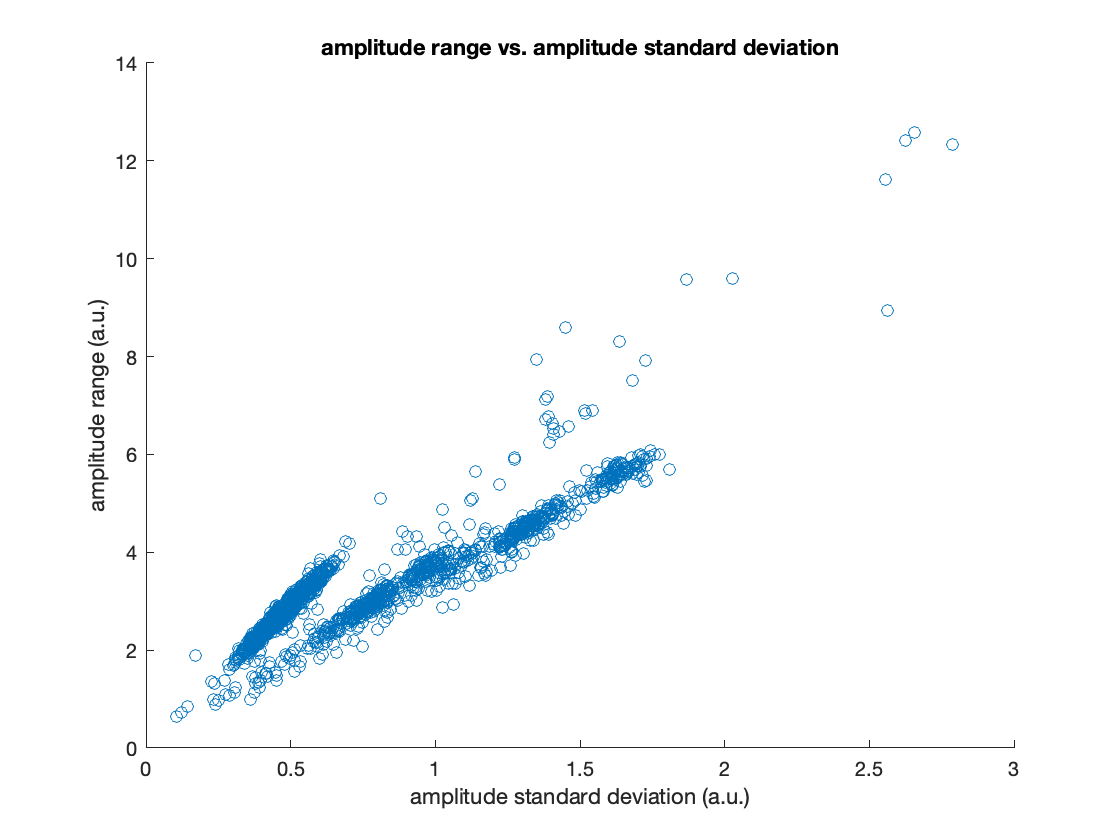


% range and stdev
figure
scatter(stdev, ranges)
xlabel('amplitude standard deviation (a.u.)')
% xlim([1 8])
ylabel('amplitude range (a.u.)')
% ylim([1 4])
title('amplitude range vs. amplitude standard deviation')

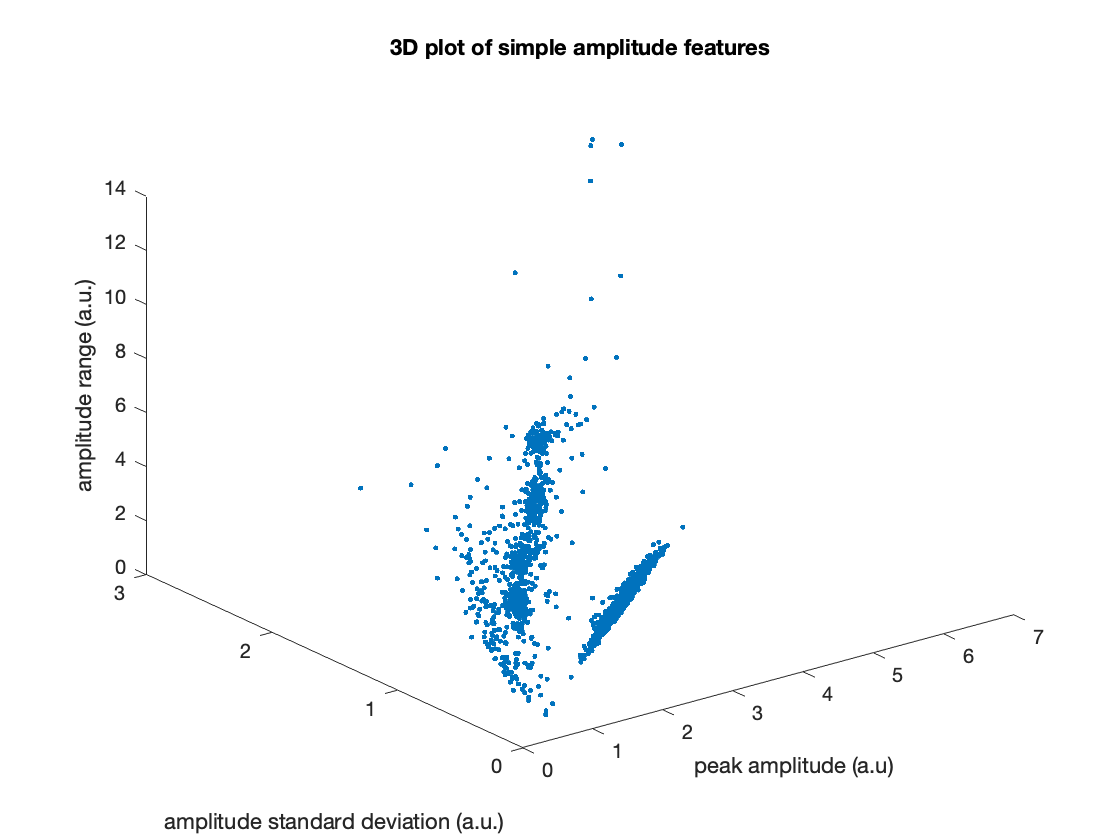


figure
plot3(pks, stdev, ranges, '.')
xlabel('peak amplitude (a.u)')
ylabel('amplitude standard deviation (a.u.)')
zlabel('amplitude range (a.u.)')
title('3D plot of simple amplitude features')

*Please see Live Script file if you would like to see the interactive version of the 3D plot / rotate it!*

**To explore whether or not simple features could cluster my data, I took the peak amplitude, amplitude range, median amplitude, and standard deviation of the amplitudes in the 100 samples around detected peaks ("clips"). The median seems to give the least helpful information, and this is evidenced by the lack of clustering visible in the peak amplitude vs. median amplitude plots. All other features show some rough clustering with one really nicely distringuished cluster about the rest. This was pretty interesting to see. I am sure more sophisticated features selection could provide even better results! In all plots but the median, I see between 3 and 5 clusters depending on how I split them (I can convince myself to lump things together or separate them out, but I am not sure which is appropriate, and I'm sure it's subjective). **